# Calculating SNR

**Calculating SNR can be difficult if the underlying signal is unknown.**  An extended discussion is in the Analyzing Harmonic Distortion  documentation section.  

A sort of ‘hack’ I sometimes use involves first computing the fft of the signal to see what its frequency content is.  

After that, since broadband noise is not completely eliminated by frequency-selective filters, I use the Savitzky-Golay filter (the sgolayfilt function) to eliminate as much of the broadband noise as I can.  (It operates as a sort of FIR filter with multiple attenuation frequencies.)  

I then subtract that result from the original signal, calculate the noise power, and the ‘filtered’ signal poweor, and be done with it.  

With respect to the ‘sinusoidal signal’ requirement, as a general rule, any periodic signal can be expressed as a sum or sinusoids of varying frequency and phase (this underlies the assumptions of the Fourier transform), so that may be enough.  

I usually work with physiologic signals that are nonlinear and nonstationary, so always challenging.  If there is some sort of magickal procedure that will always produce a robust and correct result for SNR, I have thus far not discovered it.  

I am not certain that this answers your question, so if it does not, I will delete it.  

**source: **[**https://se.mathworks.com/matlabcentral/answers/2018831-determining-signal-to-noise-ratio**](https://se.mathworks.com/matlabcentral/answers/2018831-determining-signal-to-noise-ratio)

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear; clc; close all;
format short eng                              
[ProjectFolder,AuxFcn_GS] = AuxFcn_Matlab_Startup_File_001; % Project Startup Folder & Graphical Settings

## Import Signal Data

## Load "Raw" Signal

**Note: **Details on DAQ system setting are required, to check if any hardware filters has been used.

load('E2038.mat'); 

## Signal Preprocessing

Pressure reading corrected (offset/baseline removed)

dataPoffsetCorrected = p - mean(p(1:100,:), 1);
N = length(dataPoffsetCorrected);
Fs = fs; % Sampling frequency
t = (0:N-1)'/Fs; % Time vector

## Selected Data for Analysis

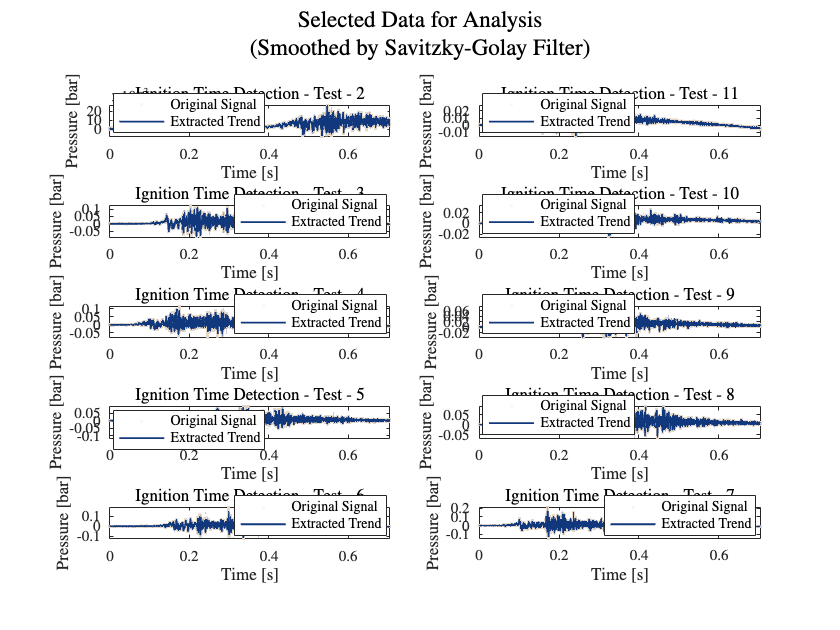

% Define number of tests based on available columns
selectedTests = [2,3,4,5,6,7,8,9,10,11];

% Define test pairs for subplot arrangement
test_pairs = [2, 11; 3, 10; 4, 9; 5, 8; 6, 7];  
rows = 5;
cols = 2;
sgolaySpan = (1000 - 1);% span must be odd and degree must be less than span.
figure;
for i = 1:size(test_pairs,1) % Loop over row pairs
    for j = 1:cols % Loop over columns
        test_index = test_pairs(i, j); % Get test number for subplot
        subplot(rows, cols, (i-1)*cols + j); % Arrange subplots
        
        % Smooth the pressure signal
        smoothed_pressure(:,test_index) = smooth(t,dataPoffsetCorrected(:,test_index), sgolaySpan, 'sgolay', 2);      
        
        % Scatter plot of original signal
        scatter(t, dataPoffsetCorrected(:, test_index), '.', ...
            'MarkerEdgeColor', AuxFcn_GS.LUCopper_Light, ...
            'MarkerEdgeAlpha', 0.2);
        hold on;
        
        % Plot extracted trend (using your blue color)
        plot(t, smoothed_pressure(:, test_index), 'Color', AuxFcn_GS.LUBlue, 'LineWidth', 1.2);
        
        % Title and labels
        title(['Ignition Time Detection - Test - ' num2str(test_index)]);
        xlabel('Time [s]');
        ylabel('Pressure [bar]');
        box on;
        legend('Original Signal', 'Extracted Trend', 'Location', 'best');
        axis tight;
        sgtitle({'Selected Data for Analysis','(Smoothed by Savitzky-Golay Filter)'})
       
    end

end
 hold off

## Compute Fourier Transform (Restrict to Positive Frequencies)

% signal = dataPoffsetCorrected;
% FFTresults = struct(); % Store results for each test
% for i = 1:size(selectedTests,2) 
% 
%  %% Compute Fourier Transform (Restrict to Positive Frequencies)
% fft_signal = abs(fft(signal(:,selectedTests(i))));
% frequencies = (0:floor(N/2)) * (Fs/N); % Positive frequency spectrum
% fft_signal = fft_signal(1:length(frequencies)); % Adjust FFT result
% 
% %% Identify Peaks in Spectrum
% [pks, locs] = findpeaks(fft_signal, 'MinPeakHeight', 0.05*max(fft_signal));
% FFTresults(i).boundaries = sort(frequencies(locs))'; % Sort detected peak frequencies
% end

## Signal Decomposition by MRA using EWT

Use ewt to obtain a multiresolution analysis (MRA) of the signal, and the corresponding analysis coefficients. Use the ten largest peaks to determine the filter passbands. Plot the signal and the MRA components.

Processing Test 2...


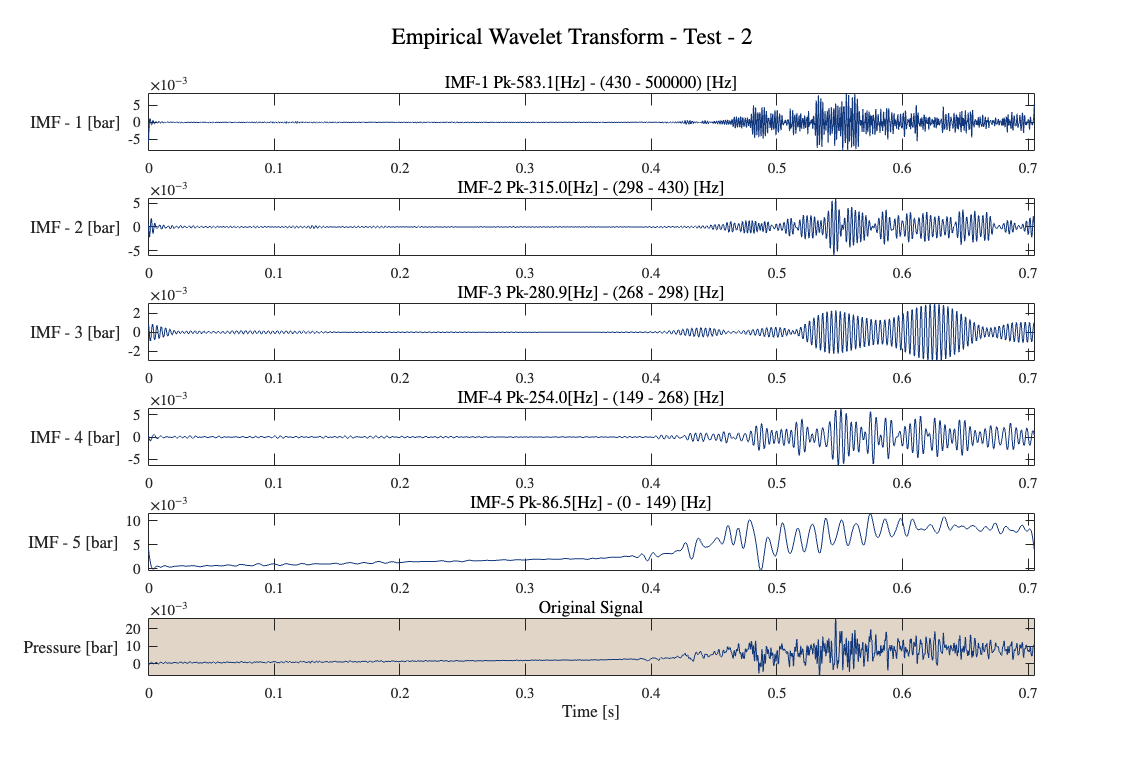

Processing Test 3...


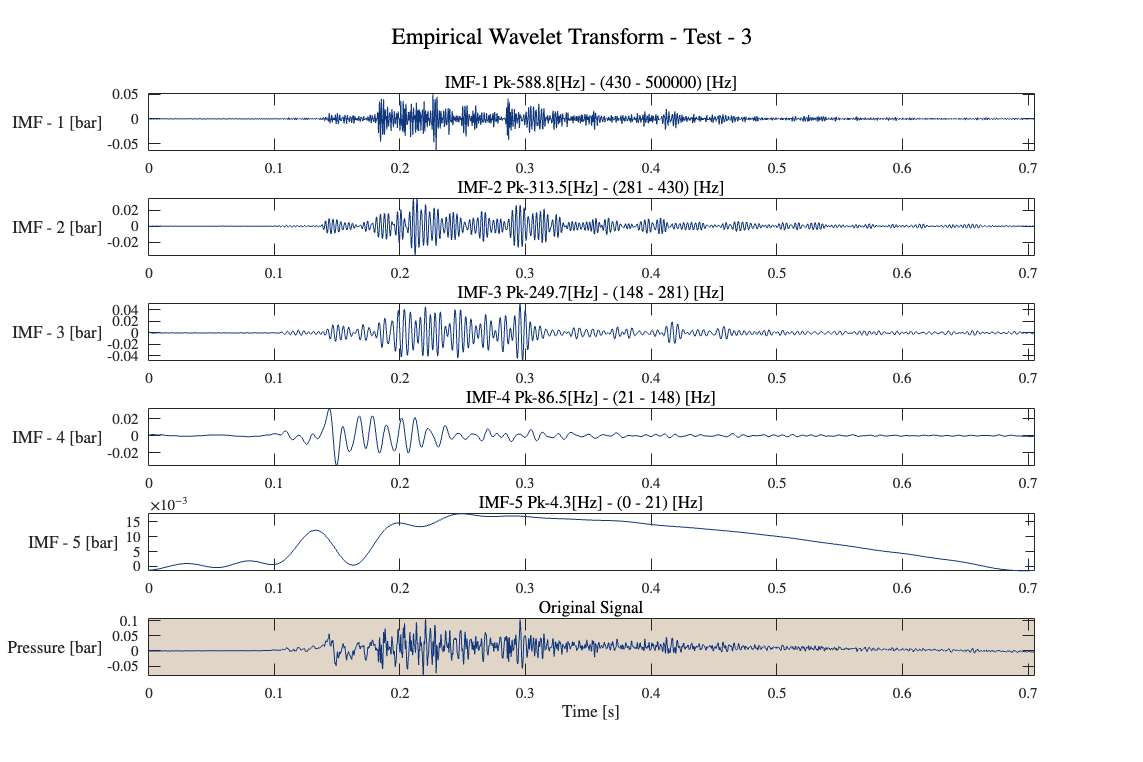

Processing Test 4...


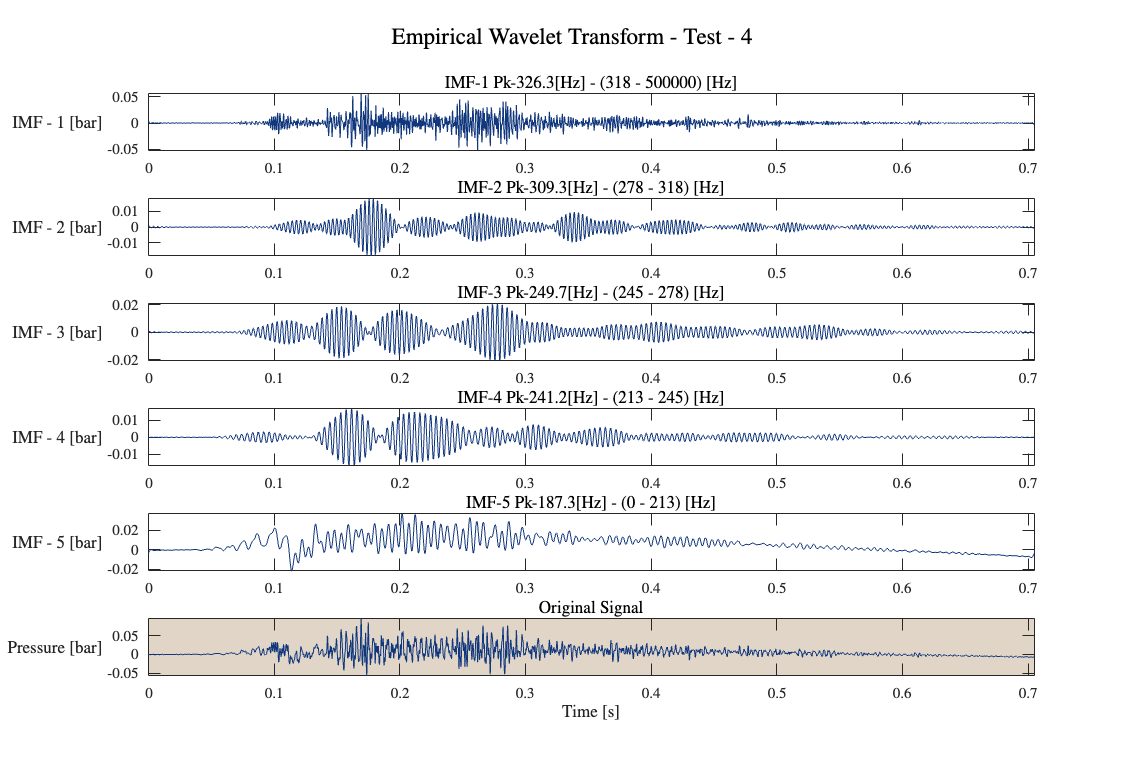

Processing Test 5...


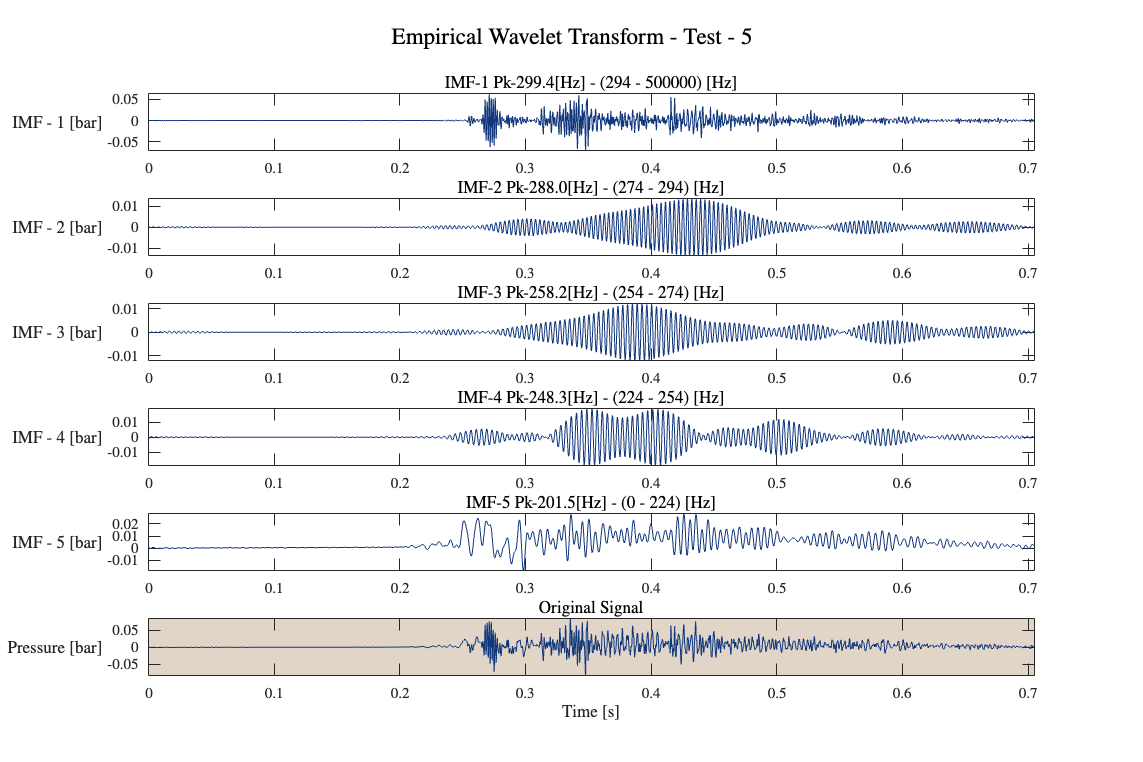

Processing Test 6...


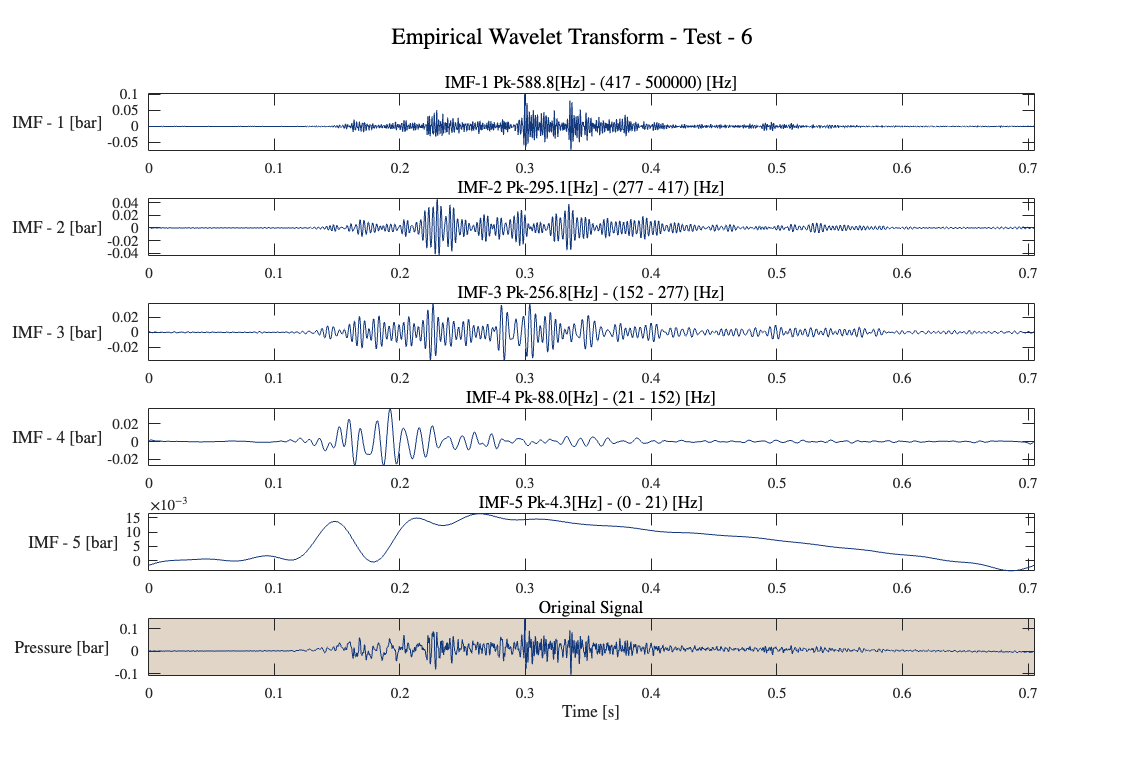

Processing Test 7...


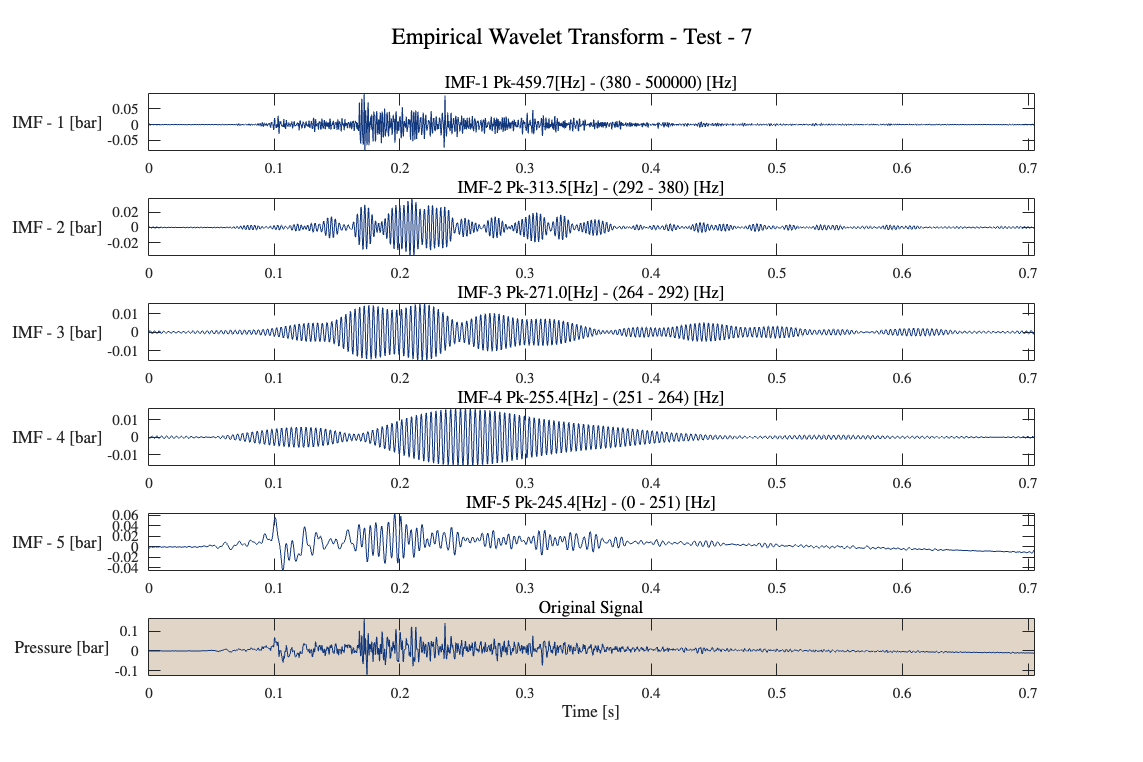

Processing Test 8...


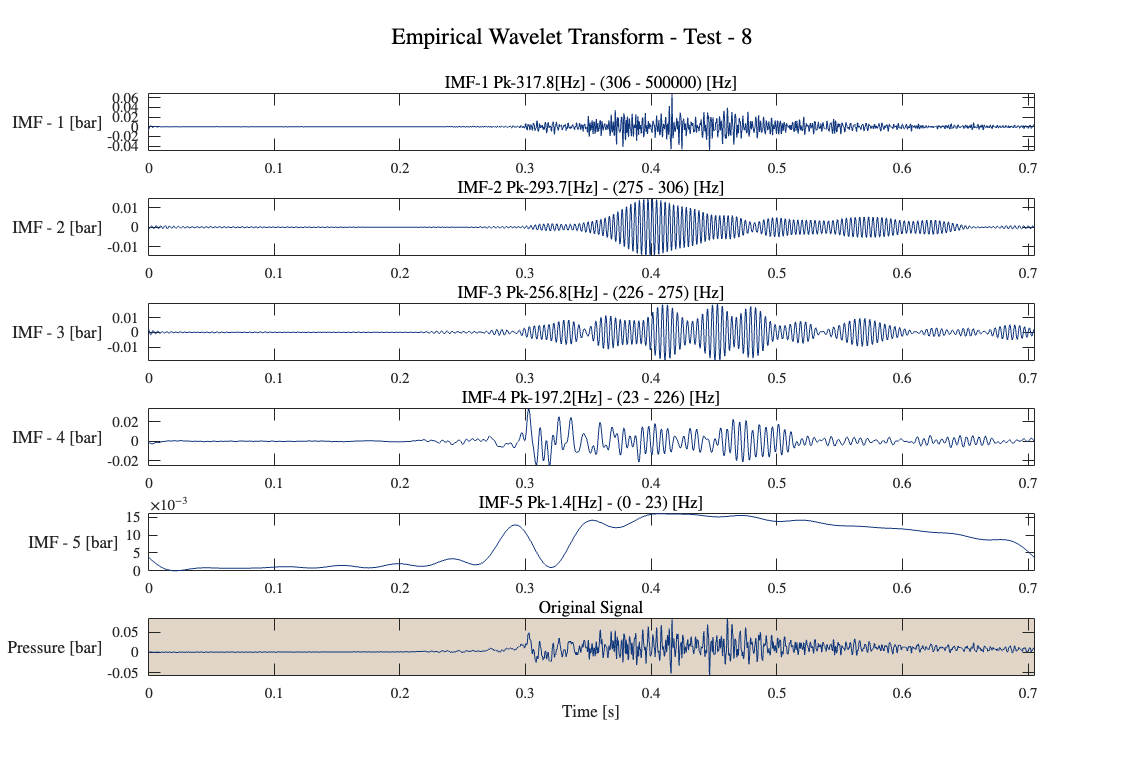

Processing Test 9...


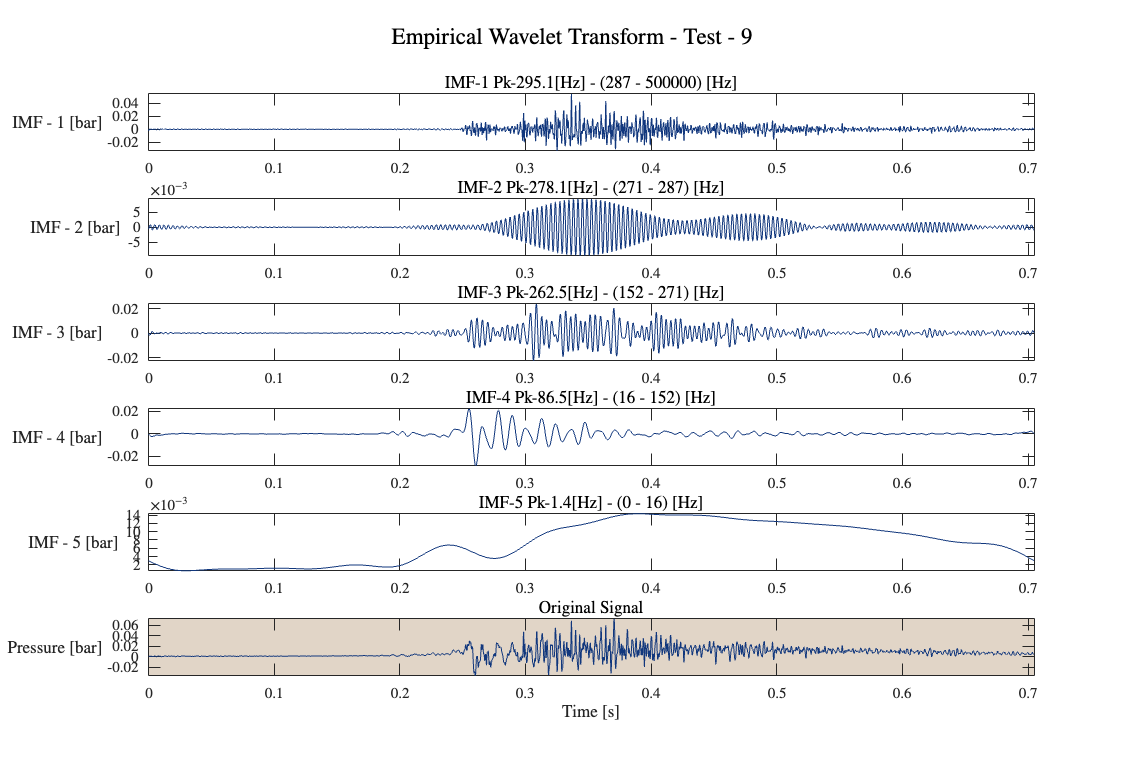

Processing Test 10...


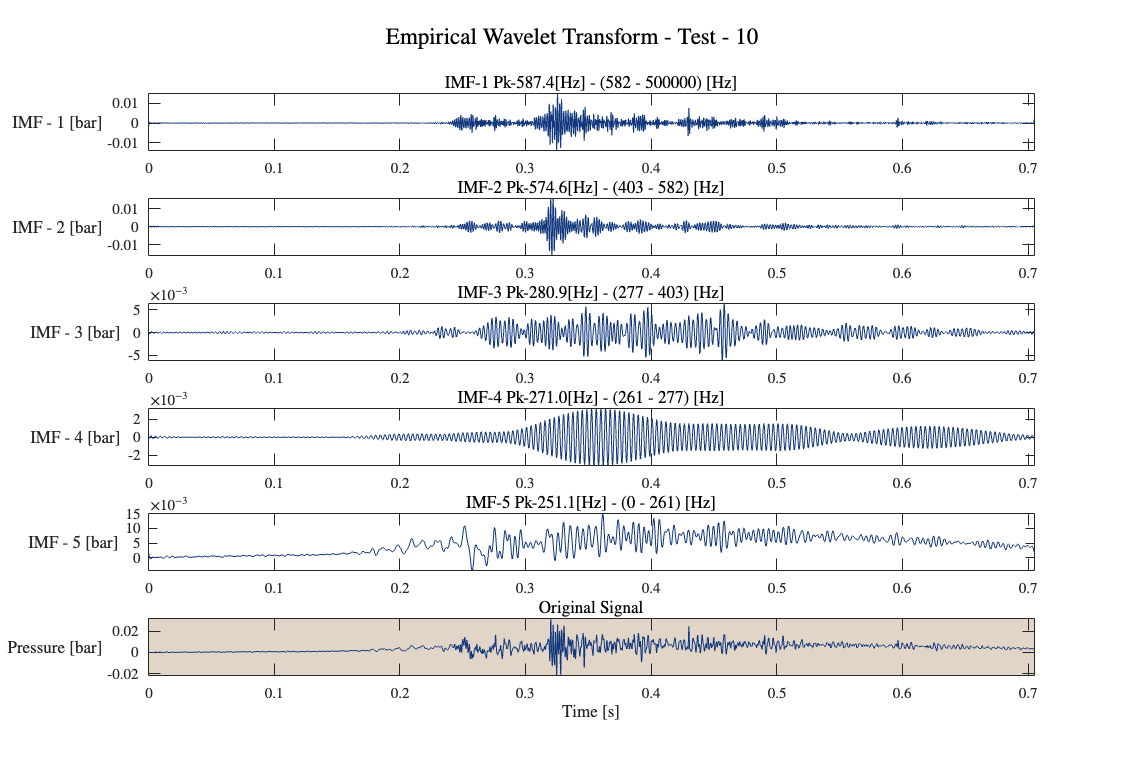

Processing Test 11...


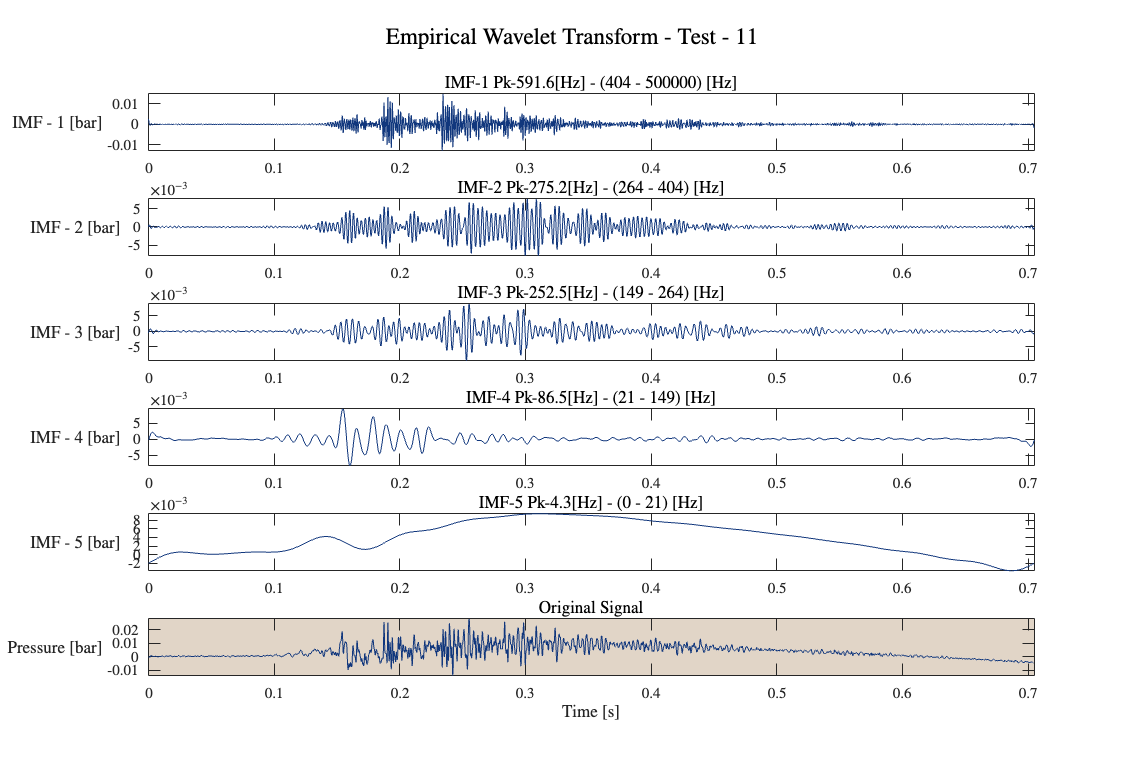

MaxNumPeaks = 5;
testNum = size(dataPoffsetCorrected,2);
results = struct(); % Store results for each test
summaryData = []; % Initialize numerical data matrix

for i = 1:size(selectedTests,2)
        fprintf('Processing Test %d...\n', selectedTests(i));
        % Perform EWT on the selected test
        [mra_ewt, cfs, wfb, info] = ewt(smooth(dataPoffsetCorrected(:, selectedTests(i)), sgolaySpan, 'sgolay', 2), 'MaxNumPeaks',MaxNumPeaks);
        % Convert peak frequencies and passbands to Hz
        PeakFrequencies = Fs * info.PeakFrequencies;
        freqPassbands = Fs * info.FilterBank.Passbands;
        % Store results for each test
        results(i).TestNumber = i;
        results(i).MRA = mra_ewt;
        results(i).Coefficients = cfs;
        results(i).WaveletBank = wfb;
        results(i).PeakFrequencies = PeakFrequencies;
        results(i).Passbands = freqPassbands;

        %% Signal Reconstruction  
        % Logical array for selecting reconstruction elements
        levelForReconstruction = [false,false,false,false,true];
        % levelForReconstruction = [false,true,true,true,true,true,true,true,true,true];
        % Sum down the rows of the selected multiresolution signals
        results(i).SignalRecon = sum(mra_ewt(:,levelForReconstruction),2);

        %% Signal Reconstruction Verification
        % Verify that summing the MRA components results in perfect reconstruction of the signal.
        results(i).SignalReconCheck = max(abs(dataPoffsetCorrected(:, i)-sum(mra_ewt,2)));
        
        % Verify energy preservation of the EWT analysis coefficients.
        signalEnergy = norm(dataPoffsetCorrected(:, i),2)^2;
        cfsenergy = sum(sum(abs(cfs).^2));
        results(i).Energy= [signalEnergy cfsenergy];
        results(i).EnergyPreservRelDiffCheck= ((cfsenergy- signalEnergy)/signalEnergy) * 100;% [%]

        % Append numerical data for structured table
        numModes = length(PeakFrequencies);
        for j = 1:numModes
            summaryData = [summaryData; i, j, PeakFrequencies(j), freqPassbands(j,1), freqPassbands(j,2)];
        end  
figure
    x0=10;
    y0=10;
    width=75;
    height=10 * MaxNumPeaks;
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
    signal = subplot(MaxNumPeaks+1,1,MaxNumPeaks+1);
    plot(t,smooth(dataPoffsetCorrected(:, selectedTests(i)), sgolaySpan, 'sgolay', 2),'Color',AuxFcn_GS.LUBlue);
    
    % p.XTickLabel={};
    % signal = gca;
    signal.Color = AuxFcn_GS.LUCopper_Light;
    signal.YLabel.Rotation = 0;
    signal.YLabel.HorizontalAlignment = 'right';
    signal.YLabel.VerticalAlignment = 'middle';
    title('Original Signal')
    sgtitle(['Empirical Wavelet Transform - Test - ',num2str(selectedTests(i))])
    ylabel('Pressure [bar]')
    xlabel('Time [s]')
    axis tight
    for k=1:MaxNumPeaks
        modes = subplot(MaxNumPeaks+1,1,k);
        plot(t,mra_ewt(:,k),'Color',AuxFcn_GS.LUBlue)
        ylabel(['IMF -  ',num2str(k), ' [bar]'])
        modes.YLabel.Rotation = 0;
        modes.YLabel.HorizontalAlignment = 'right';
        modes.YLabel.VerticalAlignment = 'middle';
        % ylabel('Pressure [bar]')
        % title(sprintf("EWT - IMF %d", k))
        title(['IMF-' num2str(k) ' Pk-' num2str(PeakFrequencies(k), '%.1f') '[Hz]' ' - ' ' (' num2str(freqPassbands(k,1), '%.0f') ' - ' num2str(freqPassbands(k,2), '%.0f') ') [Hz]'])
        axis tight
        % tiledlayout(1,MaxNumPeaks,'TileSpacing','none')
        % if k==MaxNumPeaks
        %     xlabel('Time [s]')
        % else
            s.XTickLabel={};
        % end 
    end

end